# Classifying ECG Signals (Part 1 - CNNs)

We will use deep learning to classify the same ECG dataset using two techniques:

- CNN - Convolutional Neural Network

- LSTM - Long Short-Term Memory Network

## Are You in the Correct Directory?

Your current folder browser should look like this:

% Run this to check
if isfolder('6-AdditionalFiles') && isfolder('6-Wavelets')
    disp('You are in the correct directory. Please continue.')
    addpath(genpath(pwd))
else  
    disp('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## Access and View the Dataset

The networks we train will detect whether an echocardiogram (ECG) signal comes from a heart with: 

- *Normal Sinus Rhythm (NSR)*

- * Arrythmia (ARR) *

- *Congestive Heart Failure (CHF)*

The data are 162 sample signals, sampled at a frequency (Fs) of 128Hz.

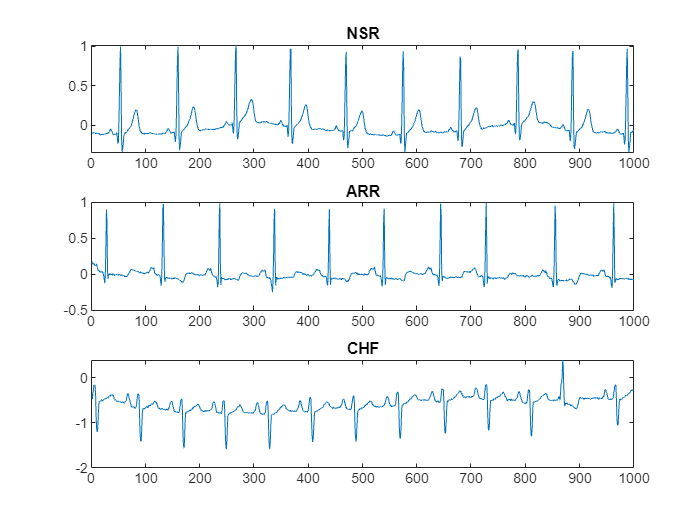

load('ECGData.mat')

subplot(3,1,1); plot(Normal_Sample); title('NSR')
subplot(3,1,2); plot(Arrythmia_Sample); title('ARR')
subplot(3,1,3); plot(HeartFailure_Sample); title('CHF')

## Preprocess Data for CNN

To train a CNN, we first have to convert our signals into images that exhibit unique characteristics for each class. One approach that works for this data set is to convert the data to the time-frequncy spectrum using [continuous wavelet transform](https://www.mathworks.com/help/wavelet/gs/continuous-wavelet-transform-and-scale-based-analysis.html).

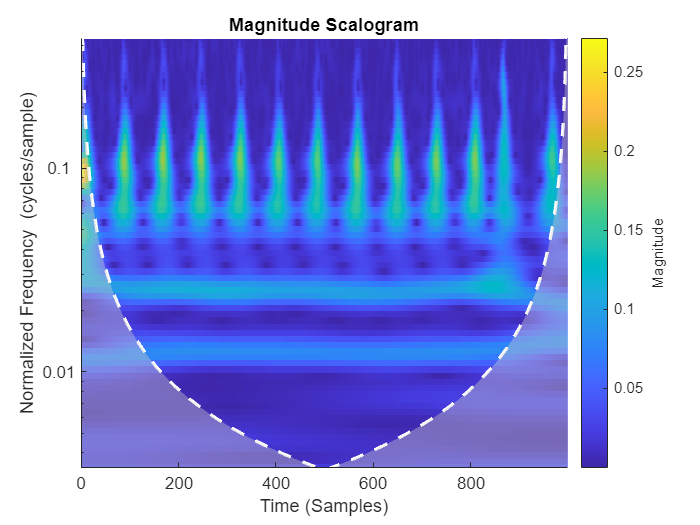

sampleCondition = HeartFailure_Sample;
cwt(sampleCondition)

Open the [`PrepareSignalData.mlx`](matlab:edit('PrepareSignalData.mlx');) file.  This script applies the continuous wavelet transform to all the siganls and saves the images in 'data' folder. This step has already been done, so **you do not run the script.** 

% edit PrepareSignalData.mlx

## View Processed Data

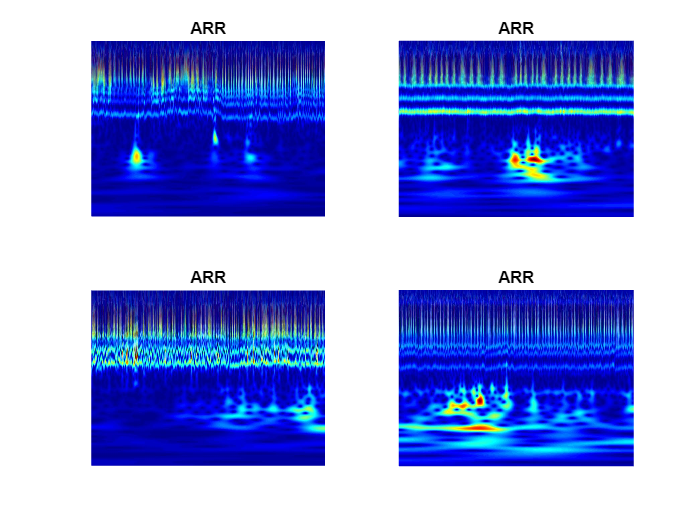

filePath = '6-Wavelets';
imds = imageDatastore(filePath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

heartRhythm = "ARR";
idx = find(string(imds.Labels) == heartRhythm);

for i = 1:4
    selectIdx = idx(randi(numel(idx)));
    im = imread(imds.Files{selectIdx});
    subplot(2,2,i)
    imshow(im)
    title(string(imds.Labels(selectIdx)));
end

## Split Data into Training and Test Images

[trainingImages, testImages] = splitEachLabel(imds, 0.8, 'randomize');

## Build CNN with Transfer Learning (programmatically)

net = imagePretrainedNetwork("squeezenet");

Resize the images to fit the network we will build. 

inputSize = net.Layers(1).InputSize(1:2);
trainingImagesR = augmentedImageDatastore(inputSize, trainingImages);
testImagesR = augmentedImageDatastore(inputSize, testImages);

**Replace Final Layers**

The convolutional layers within the network are responsible for extracting features from images, which are then utilized by the final learnable layer for categorizing the input image. In SqueezeNet, for instance, the layer named 'conv10' plays a crucial role in merging the extracted features to predict class probabilities. To adapt a pretrained network for classifying a new set of images, it's essential to substitute this layer with new layers tailored to the new dataset.

Find the names of the layer to replace. 

net.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'          Dropout                      50% dropout
     2   'conv10'         2-D Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'    ReLU                         ReLU
     4   'pool10'         2-D Global Average Pooling   2-D global average pooling
     5   'prob'           Softmax                      softmax
     6   'prob_flatten'   Flatten                      Flatten

Typically, the last layer with learnable parameters in many networks is a fully connected layer. However, networks like SqueezeNet use a 1-by-1 convolutional layer as the last learnable layer. In such scenarios, it's necessary to replace this convolutional layer with a new one. 

The new layer should have a number of filters matching the number of new classes. To ensure the new layers learn at a faster rate compared to the pre-existing layers, it's recommended to increase the values of WeightLearnRateFactor and BiasLearnRateFactor for the convolutional layer.

classNames = categories(trainingImages.Labels);
numClasses = numel(classNames);
newConvLayer =  convolution2dLayer([1, 1],numClasses,'WeightLearnRateFactor',10,'BiasLearnRateFactor',10,"Name",'new_conv');
net = replaceLayer(net,"conv10",newConvLayer);

net.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'          Dropout                      50% dropout
     2   'new_conv'       2-D Convolution              3 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'    ReLU                         ReLU
     4   'pool10'         2-D Global Average Pooling   2-D global average pooling
     5   'prob'           Softmax                      softmax
     6   'prob_flatten'   Flatten                      Flatten

## Set Hyperparameters and Train Network

Use the following training options and save them to variable "opts"

- `InitialLearnRate 0.0001`

- `MaxEpochs        12 `

- `MiniBatchSize    10 `

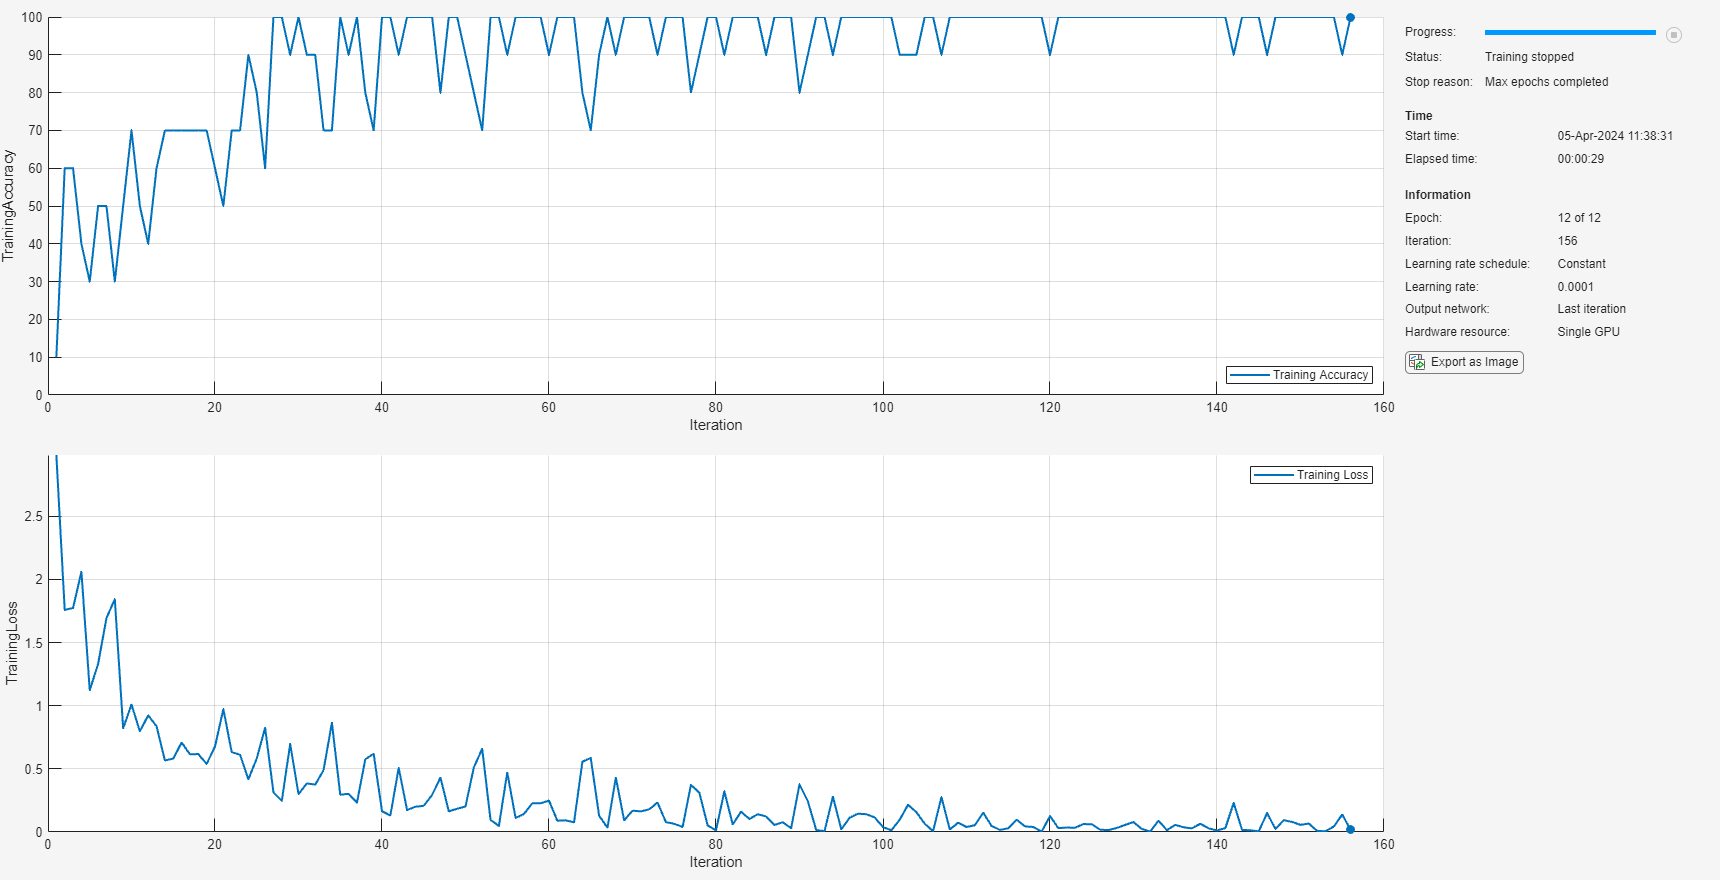

opts = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.0001, ...
    'MaxEpochs', 12, ...
    'MiniBatchSize', 10, ...
    'Plots', 'training-progress', ...
    "Metrics","accuracy", ...
    "Verbose",false);
    
ECGNet = trainnet(trainingImagesR, net, "crossentropy",opts);

## Test the Network

scores = minibatchpredict(ECGNet, testImagesR);
labels = scores2label(scores, classNames);
accuracy = sum(labels == testImages.Labels)*100 / numel(labels)

accuracy = 87.5000

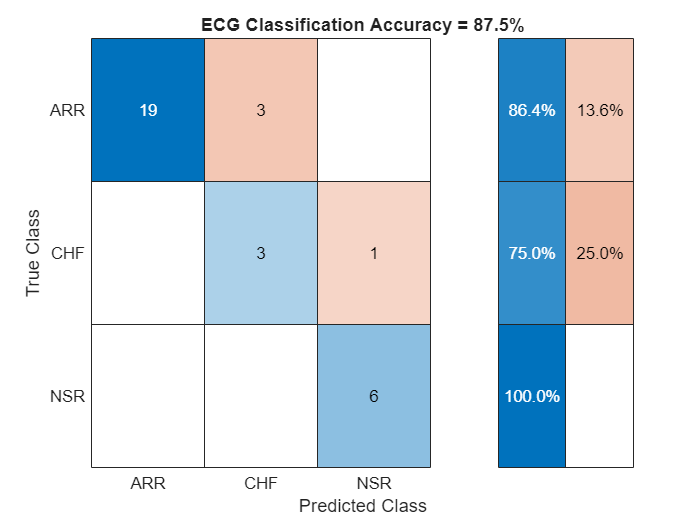

cm = confusionchart(labels, testImages.Labels);
cm.RowSummary = 'row-normalized';
cm.Title = ['ECG Classification Accuracy = ' num2str(accuracy) '%'];

## Classify Signals using LSTM

Try out part 2 of the exercise.

edit Solution_ECG_LSTM.mlx

*Copyright 2024 The MathWorks, Inc.*